clear
clearvars
syms theta_1 theta_2 theta_3 theta_4 P_x P_y P_z
assume(theta_1,'real')
assume(theta_2,'real')
assume(theta_3,'real')
assume(theta_4,'real')

L=[0.145 0.107 0.107 0.09]*100

L =    14.5000   10.7000   10.7000    9.0000


DH=[0, L(1), 0, (pi/2), 0, 0;
       0, 0, (L(2)), 0, 0, 0;
       0, 0, (L(3)),0, 0, 0;
       0, 0, L(4), pi/2 , 0, 0]

DH =          0   14.5000         0    1.5708         0         0
         0         0   10.7000         0         0         0
         0         0   10.7000         0         0         0
         0         0    9.0000    1.5708         0         0



Li(1)=Link(DH(1,:));
Li(2)=Link(DH(2,:));
Li(3)=Link(DH(3,:));
Li(4)=Link(DH(4,:));

Robot_1=SerialLink(Li,'name','Robot');
%Robot_q_1.tool = [1 0 0 L(4); 0 0 -1 0; 0 1 0 0; 0 0 0 1];
%A=simplify(Robot_q_1.A([1 2 3 4],[theta_1 theta_2 theta_3 theta_4]),"Steps",200)







q_1=[0.7853981633974483;
0.6530481254872835;
-1.7459907305629048;
1.6165413806739202]'

q_1 =     0.7854    0.6530   -1.7460    1.6165


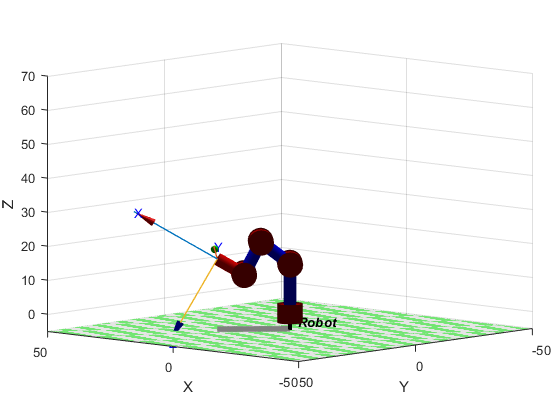

Robot_1.plot(q_1,'view',[150 30],'workspace',[-50 50 -50 50 -5 70],'joints','jointdiam',3);

Robot_1.fkine(q_1)

ans =     0.6124    0.7071    0.3536   15.0000
    0.6124   -0.7071    0.3536   15.0000
    0.5000    0.0000   -0.8660   16.0000
         0         0         0    1.0000


syms L_1 L_2 L_3 L_4
L=[L_1 L_2 L_3 L_4]

$$L = \left(\begin{array}{cccc} L_{1} & L_{2} & L_{3} & L_{4} \end{array}\right)$$


DHSym=[0, L(1), 0, sym(pi)/2, 0, 0;
       0, 0, L(2), 0, 0, 0;
       0, 0, L(3),0, 0, 0;
       0, 0, L(4), sym(pi)/2 , 0, 0]

$$DHSym = \left(\begin{array}{cccccc} 0 & L_{1} & 0 & \frac{\pi }{2} & 0 & 0\\ 0 & 0 & L_{2} & 0 & 0 & 0\\ 0 & 0 & L_{3} & 0 & 0 & 0\\ 0 & 0 & L_{4} & \frac{\pi }{2} & 0 & 0 \end{array}\right)$$


LiSym(1)=Link(DHSym(1,:));
LiSym(2)=Link(DHSym(2,:));
LiSym(3)=Link(DHSym(3,:));
LiSym(4)=Link(DHSym(4,:));
q_1=[0 0 0 0];
Robot_1_sym=SerialLink(LiSym,'name','Robot Sym')

 
Robot_1_sym = 
 
Robot Sym (4 axis, RRRR, stdDH, fastRNE)                         
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        L_1|          0|       pi/2|          0|
|  2|         q2|          0|        L_2|          0|          0|
|  3|         q3|          0|        L_3|          0|          0|
|  4|         q4|          0|        L_4|       pi/2|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1      

A=simplify(Robot_1_sym.A([1 2 3 4],[theta_1 theta_2 theta_3 theta_4]),"Steps",200)

$$A = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \sigma_{1}\,\cos\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sigma_{2}\\ \sigma_{3}\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \sigma_{1}\,\sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{2}\\ \sigma_{1} & 0 & -\sigma_{3} & L_{1}+L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\sin\left(\theta_{2}\right)+L_{4}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\cos\left(\theta_{2}\right)+L_{4}\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$


syms beta R D_z D_r

%theta_1=atan2(P_y,P_x)
Eq1=tan(theta_1)==P_y/P_x

$$Eq1 = \tan\left(\theta_{1}\right)=\frac{P_{y}}{P_{x}}$$

Eq2=simplify(A(1,4).^2+A(2,4).^2,"Steps",100);
Eq2=Eq2==P_x^2+P_y^2

$$Eq2 = {\left(L_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\cos\left(\theta_{2}\right)+L_{4}\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\right)}^{2}={P_{x}}^{2}+{P_{y}}^{2}$$



Eq3=simplify(A(3,4),"Steps",100)==P_z

$$Eq3 = L_{1}+L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\sin\left(\theta_{2}\right)+L_{4}\,\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)=P_{z}$$


Eq2=L_3*cos(theta_2 + theta_3) + L_2*cos(theta_2) == D_r

$$Eq2 = L_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\cos\left(\theta_{2}\right)=D_{r}$$

%D_r=R-L_4*cos(beta)
%R=sqrt(P_x^2+P_y^2)
Eq3=L_3*sin(theta_2 + theta_3) + L_2*sin(theta_2)== D_z

$$Eq3 = L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\sin\left(\theta_{2}\right)=D_{z}$$

%D_z=P_z-L_4*sin(beta) -L_1
Eq4=theta_2+theta_3+theta_4==beta

$$Eq4 = \theta_{2}+\theta_{3}+\theta_{4}=\beta$$

[theta_2s,theta_3s]=solve([Eq2;Eq3],[theta_2 theta_3]);

theta_2=simplify(theta_2s(1),"Steps",100)

$$theta\_2 = 2\,\mathrm{atan}\left(\frac{2\,D_{z}\,L_{2}+\sqrt{-{D_{r}}^{4}-2\,{D_{r}}^{2}\,{D_{z}}^{2}+2\,{D_{r}}^{2}\,{L_{2}}^{2}+2\,{D_{r}}^{2}\,{L_{3}}^{2}-{D_{z}}^{4}+2\,{D_{z}}^{2}\,{L_{2}}^{2}+2\,{D_{z}}^{2}\,{L_{3}}^{2}-{L_{2}}^{4}+2\,{L_{2}}^{2}\,{L_{3}}^{2}-{L_{3}}^{4}}}{{D_{r}}^{2}+2\,D_{r}\,L_{2}+{D_{z}}^{2}+{L_{2}}^{2}-{L_{3}}^{2}}\right)$$

theta_3=simplify(theta_3s(1),"Steps",100)

$$theta\_3 = -2\,\mathrm{atan}\left(\frac{\sqrt{\left(-{D_{r}}^{2}-{D_{z}}^{2}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}\right)\,\left({D_{r}}^{2}+{D_{z}}^{2}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}\right)}}{{D_{r}}^{2}+{D_{z}}^{2}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}}\right)$$


[Stheta_1,Stheta_2,Sd_3]=vpasolve(H_30(1:3,4)==P1,[theta_1,theta_2,d_3]);
theta_1s(1)=double(Stheta_1);theta_2s=double(Stheta_2);
d_3s(1)=double(Sd_3);

Se resuelve para todos los puntos de la trayectoria:

for i=1:N
    [Stheta_1,Stheta_2,Sd_3]=vpasolve(H_30(1:3,4)==(P1+i.*deltaP),[theta_1,theta_2,d_3]);
    theta_1s(i+1)=double(Stheta_1);
    theta_2s(i+1)=double(Stheta_2);
    d_3s(i+1)=double(Sd_3);
end

Se genera la animación y se guardan las posiciones:

posF=zeros([16,3]);
for i=1:length(theta_1s)
    q=[theta_1s(i) theta_2s(i) d_3s(i)];
    Robot_5.animate(q)
    pause(0.5)
    H=Robot_5.fkine(q);
    posF(i,:)=H(1:3,4);
end